# Optimal Waveform Design for Target Identification

## Create Targets

First, create two target impulse responses. According to [1], I use a regularized s,oothe impulse response that is the sum of multiple Gaussian pulses.

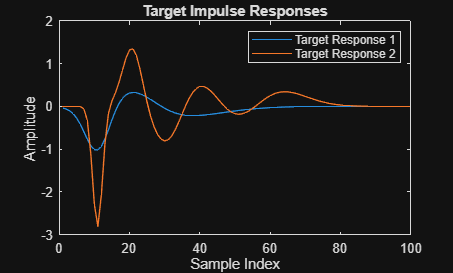

function out = generateNormalPulse(n,b)
    t = linspace(0,10,100);
    out =  n/sqrt(pi)*exp(-n^2*(t-b).^2);
end

h1 = generateNormalPulse(-2,1) + ...
     generateNormalPulse(1,2) + ...
     generateNormalPulse(-.5,3);
h2 = 0;
nTrials = 6;
for i = 1:nTrials
    h2 = h2+generateNormalPulse((-1)^i*5/i,i);
end

% Plot the impulse repsonses and their power spectrum
figure;
plot(real(h1)); hold on;
plot(real(h2))
legend({'Target Response 1','Target Response 2'})
xlabel('Sample Index')
ylabel('Amplitude')
title('Target Impulse Responses')

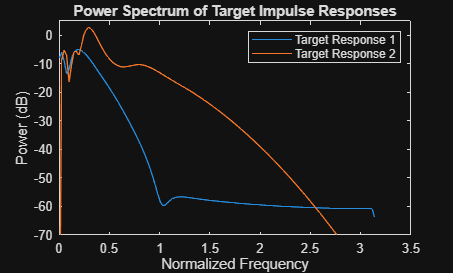


figure; 
[pxx1,w] = periodogram(h1);
plot(w,pow2db(pxx1))
hold on;
[pxx2,w] = periodogram(h2);
plot(w,pow2db(pxx2))
ylim([-70 5])
legend({'Target Response 1','Target Response 2'})
ylabel('Power (dB)')
xlabel('Normalized Frequency')
title('Power Spectrum of Target Impulse Responses')

## Determine Optimal Waveform

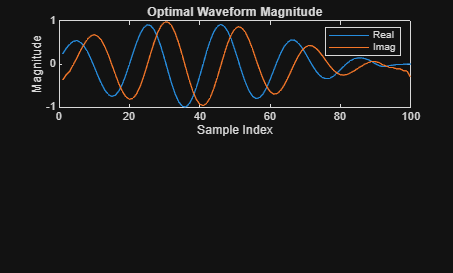

% Create Target Transfer Matrices
H1 = tril(toeplitz(h1));
H2 = tril(toeplitz(h2));

% Difference between target impulse responses
H = H1 - H2;
% Optimization
[V,D] = eig(H'*H);
[~,idx] = max(diag(D)); % find max eigenvalue

wfm = hilbert(V(:,idx)); % get complex baseband signal
wfm = wfm / max(abs(wfm)); % set maximum amplitude to unity power

figure; 
subplot(2,1,1)
plot(real(wfm));
hold on
plot(imag(wfm))
title('Optimal Waveform Magnitude')
ylabel('Magnitude')
xlabel('Sample Index')
legend({'Real','Imag'})

## Compare with FMCW Waveform

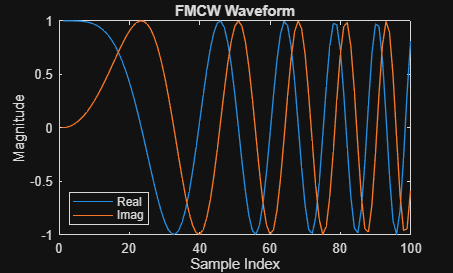

% FMCW (Popular waveform but not optimal for this task)
waveform = phased.FMCWWaveform('SweepBandwidth',100.0e3,...
    'OutputFormat','Sweeps','NumSweeps',1);
fmcw = waveform();

figure;
plot(real(fmcw))
hold on;
plot(imag(fmcw))
title('FMCW Waveform')
ylabel('Magnitude')
xlabel('Sample Index')
legend({'Real','Imag'},"Location","southwest")

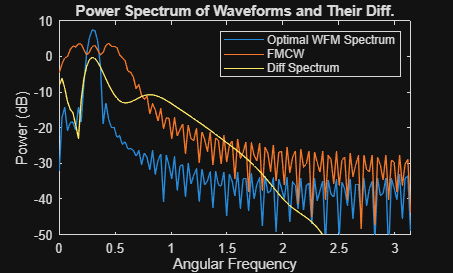


figure; 
[pxxWFM,w] = periodogram(wfm);
plot(w,pow2db(pxxWFM))
hold on;
[pxxFMCW,w] = periodogram(fmcw);
plot(w,pow2db(pxxFMCW))
[pxxDif,w] = periodogram(H(:,1));
plot(w,pow2db(pxxDif))
ylim([-50 10])
xlim([0,pi])
xlabel('Angular Frequency')
ylabel('Power (dB)')
legend({'Optimal WFM Spectrum','FMCW','Diff Spectrum'})
title('Power Spectrum of Waveforms and Their Diff.')

Notice the strong correlation between the optimal waveform's spectrum and the difference spectrum.

## Validate Solution

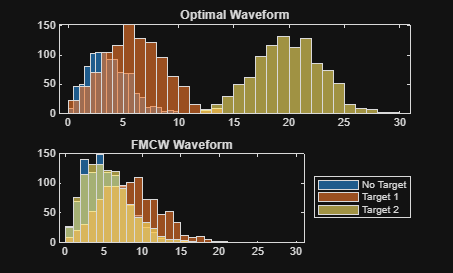

nTrials = 1000;
noisePower = 0.35;
% Divde by 2 because complex noise and sqrt because var(aX) = (a^2)(X^2)
noise = sqrt(noisePower/2)*complex(randn(nTrials,size(h1,2)),randn(nTrials,size(h1,2)));
noiseResults = abs(noise * wfm);
tgt1Results = abs((h1+noise) * wfm);
tgt2results = abs((h2+noise) * wfm);

figure;
subplot(2,1,1)
ax = histogram(noiseResults);
hold on;
histogram(tgt1Results);
histogram(tgt2results)
title('Optimal Waveform')

subplot(2,1,2) 
nTrials = 200;
noiseResults = abs(noise * fmcw);
tgt1Results = abs((h1+noise) * fmcw);
tgt2results = abs((h2+noise) * fmcw);
histogram(noiseResults);
hold on;
histogram(tgt1Results);
histogram(tgt2results)
title('FMCW Waveform')

xlim(ax.Parent.XLim)
legend({'No Target','Target 1','Target 2'},'Location','eastoutside')

## References

[1] [Impulse Response Target Study](https://apps.dtic.mil/sti/tr/pdf/ADA044801.pdf), pg. 24